# Week of September 23rd

#### By Bora Basyildiz 

## I. Interpolation Integration 

For this week, I used the interpolation  integration provided by Professor Strong, and I worked with this code in two separate ways. First, I compared its outputs to the integration from the *trapz* function. First, I observed that the outputs from the same set of values and points were different. For the BSI impact on the same point, we the following values 

p = [-1;0;0];
C1 = Curve_Gen('circle',500);
s = 1:length(C1); 
T1 = Derivative(C1); 
Biot_Savart(C1,T1,p,0)

ans = 1.0e+02 *

   1.760800282941242
   0.003535884216204
  -0.000022261726209


Scott_Integral

ans =      0


ans =      3.847964436005157e-04


ans =     -4.844696998885793e-06


First, we note that both the Biot_Savart integral and Scott_Integral has different directions and magnitudes. I tried to look into the difference for this, but I am still new to the interpolation code. I will likely have to sit down with Professor Strong to discuss why this might be the case. This difference in values is troubling, and merits more discussion on which value is correct. 

I also implemented the Interpolation Integration into the Curve_Evol 

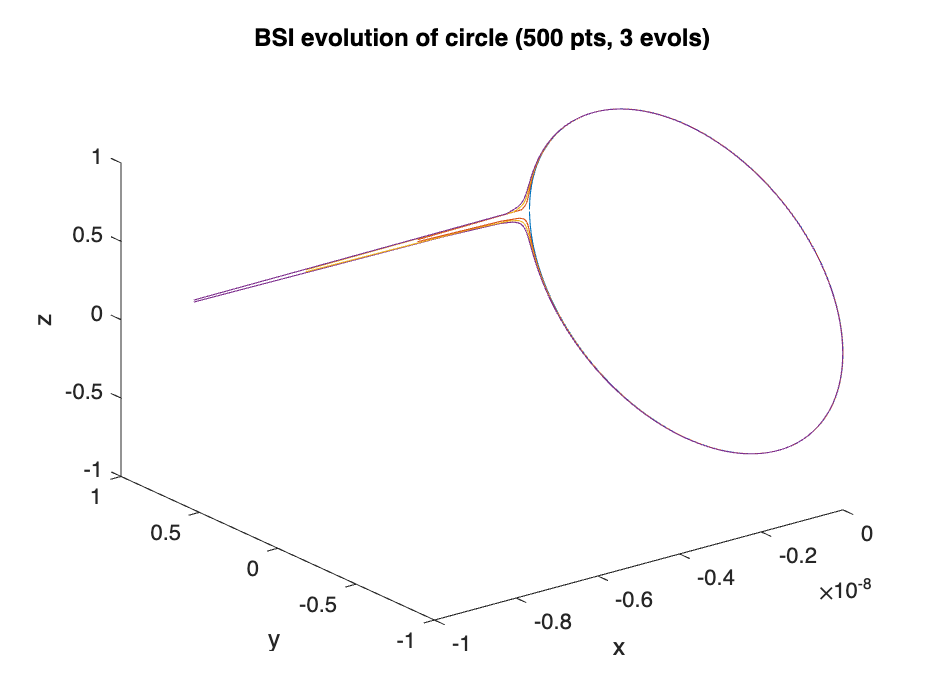

Curve_Evol('circle','BSI',500,3)

I saw that the only impact that the interpolation integration had was on points near the origin. I shifted the integration domain such that each point is integrating on its nearest components, but still, this problem consisted. It is yet to be seen whether this issue is systemic or an implemention issue. 

## II. Implicit Evolution 